clear;
clc;
close all;

video = VideoReader('acm.MP4');
for img = 1:video.NumFrames
    filename = strcat('frame', num2str(img), '.jpg');
    image_data= imread(filename);
    x=[2260 1930 1580];
    y=[1397 1397 1397];
    pixel_data=impixel(rgb2gray(image_data),x,y);
    temp_1(img)=pixel_data(1,1);  
    temp_2(img)=pixel_data(2,1);
    temp_3(img)=pixel_data(3,1);
end

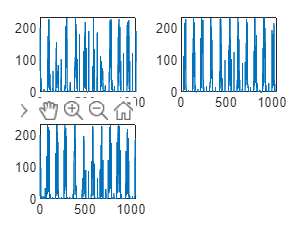

x = 1:1059;
tiledlayout('flow')

nexttile
plot(x,temp_1)

nexttile
plot(x,temp_2)

nexttile
plot(temp_3)